# Problem 2

clc;
clear;
close all;

## Setup

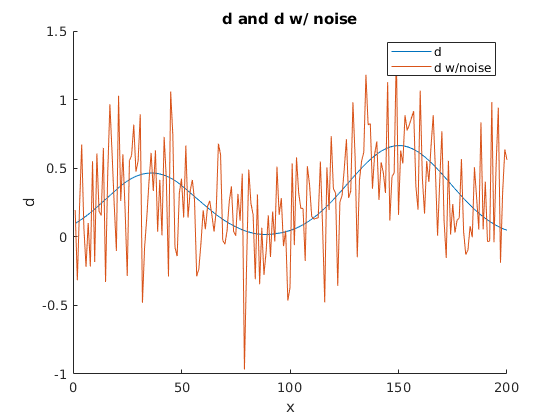

% set rng seed
rng(1000);

% Create 200 points (x and x' have the same domain)
x = linspace(0, 1, 200);

% Create the blurring operator k
k = @(m, n) (1/numel(m))*...
            (0.2^-2)*...
            max(zeros(numel(m),numel(n)),...
            0.2-abs(repmat(m',1,numel(n))-repmat(n,numel(m),1)));

% Now create m_true function
m_true = @(c) ...
    ((0.1<c & c<0.25)*0.75 + ...
    (0.3<c & c<0.32)*0.25 + ...
    (0.5<c & c<1).*(sin(2*pi*c).^4))';

% Add le gaussian noise with 0 mean, 0.1 variance
n = randn(numel(x),1)*sqrt(0.1);

% Now calculate d and dn
d = k(x,x)*m_true(x);
dn = d + n;

% plot d and d with noise
figure; hold on; a = plot(d); b = plot(dn);
xlabel('x'); ylabel('d'); title('d and d w/ noise');
legend([a,b],{'d','d w/noise'})

% do svd on k
[U,S,V] = svd(k(x,x));

## Part (a)

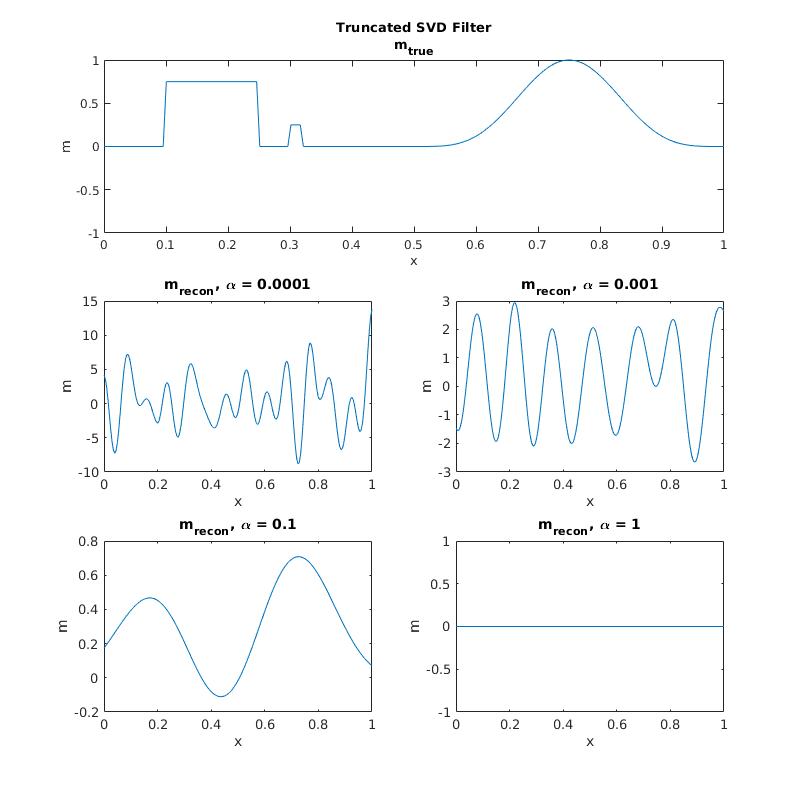

% calculate TSVD filters (alpha = 0.0001, 0.001, 0.1, 1)
alpha = [0.0001, 0.001, 0.1, 1];
[r_k, c_k] = size(k(x,x)); % get size of k
k_inv = zeros(r_k, c_k, numel(alpha)); % initial storage for k_inv
e_m = numel(m_true(x)); % get size of m
m_recon = zeros(e_m, numel(alpha)); % initial storage for m_recon
for i=1:numel(alpha)
    % Find eigenvalues greater than alpha and use as a mask
    mask = diag(S.^2) > alpha(i);
    
    % Now truncate with mask and invert the singular values
    S_inv = diag(diag(1./S).*mask);
    
    % Now find the inverse
    k_inv(:,:,i) = V*S_inv*U';
    
    % Reconstruct
    m_recon(:,i) = k_inv(:,:,i)*dn;
end

% plot everything
figure('Position', [400, 100, 800, 800]);
subplot(3,2,[1,2]); % subplot with m_true on top
plot(x,m_true(x)); % plot m_true
xlim([0,1]); ylim([-1,1]);
title({'Truncated SVD Filter', 'm_{true}'}); xlabel('x'); ylabel('m');
for i=1:numel(alpha) % plot reconstructed m for each alpha
    subplot(3,2,i+2);
    plot(x,m_recon(:,i));
    xlim([0,1]); %ylim([-1,1]);
    title(['m_{recon}, \alpha = ', num2str(alpha(i))]); xlabel('x'); ylabel('m');
end

## Part (b)

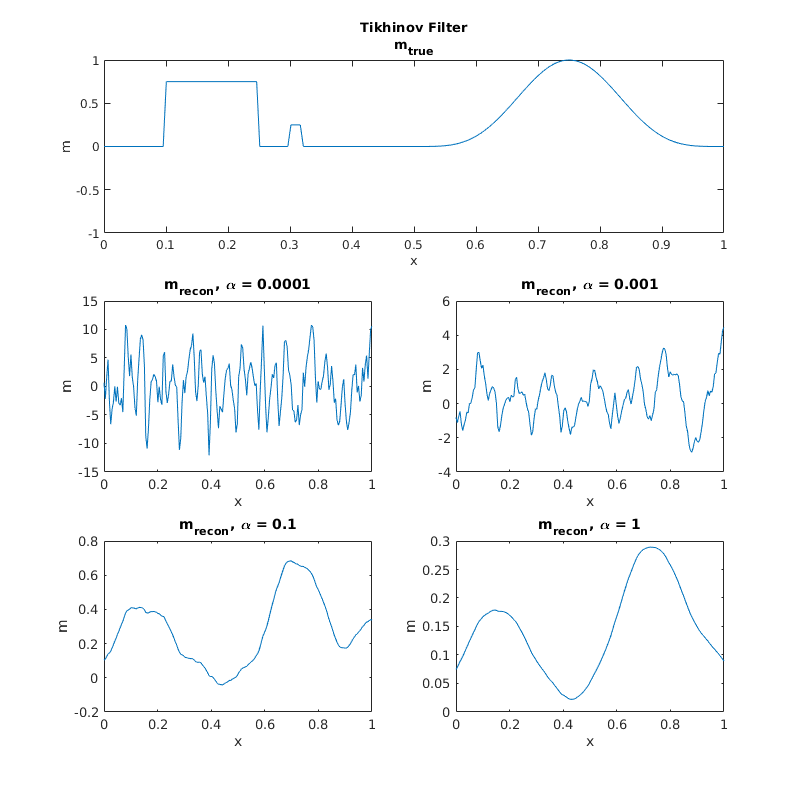

% calculate Tikhinov filters (alpha = 0.0001, 0.001, 0.1, 1)
k_inv_tk = zeros(r_k, c_k, numel(alpha)); % initial storage for k_inv
m_recon_tk = zeros(e_m, numel(alpha)); % initial storage for m_recon
for i=1:numel(alpha)
    % Create Tikhinov mask
    mask = diag(S.^2)./(diag(S.^2) + alpha(i));
    
    % Now truncate with mask and invert the singular values
    S_inv = diag(diag(1./S).*mask);
    
    % Now find the inverse
    k_inv_tk(:,:,i) = V*S_inv*U';
    
    % Reconstruct
    m_recon_tk(:,i) = k_inv_tk(:,:,i)*dn;
end

% plot everything
figure('Position', [400, 100, 800, 800]);
subplot(3,2,[1,2]); % subplot with m_true on top
plot(x,m_true(x)); % plot m_true
xlim([0,1]); ylim([-1,1]);
title({'Tikhinov Filter', 'm_{true}'}); xlabel('x'); ylabel('m');
for i=1:numel(alpha) % plot reconstructed m for each alpha
    subplot(3,2,i+2);
    plot(x,m_recon_tk(:,i));
    xlim([0,1]); %ylim([-1,1]);
    title(['m_{recon}, \alpha = ', num2str(alpha(i))]); xlabel('x'); ylabel('m');
end

## Part (c)

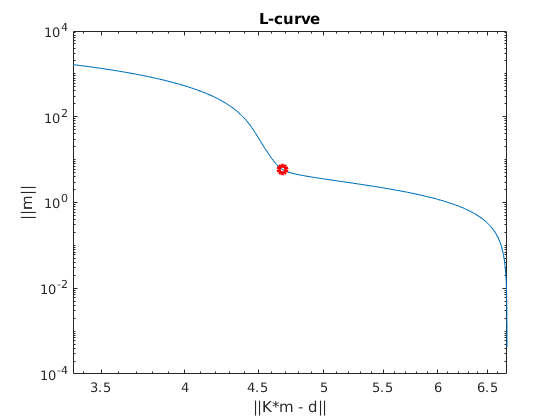

% calculate misfit and regularization values
alpha_list = logspace(-6,4,1000);
m_alpha = zeros(e_m,numel(alpha_list));
misfit = zeros(numel(alpha_list),1);
reg = zeros(numel(alpha_list),1);
for i=1:numel(alpha_list)
    % calculate m_alpha
    m_alpha(:,i) = (k(x,x)'*k(x,x) +...
        alpha_list(i) * eye(numel(diag(S))))\(k(x,x)'*dn);
    
    % calculate misfit and regularization term for alpha
    misfit(i) = norm(k(x,x)*m_alpha(:,i) - dn);
    reg(i) = norm(m_alpha(:,i));
end

% plot L-curve
crit = 450; % set index of max curvature
figure; loglog(misfit, reg); hold on;
loglog(misfit(crit), reg(crit), 'ro', 'Linewidth', 3); % circle optimal value
xlabel('||K*m - d||'); ylabel('||m||'); title('L-curve');

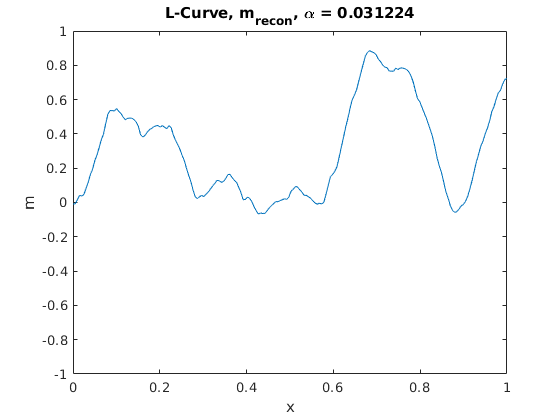

% plot the reconstruction
figure; plot(x,m_alpha(:,crit)); xlim([0,1]); ylim([-1,1]);
title(['L-Curve, m_{recon}, \alpha = ', num2str(alpha_list(crit))]);
xlabel('x'); ylabel('m');

## Part (d)

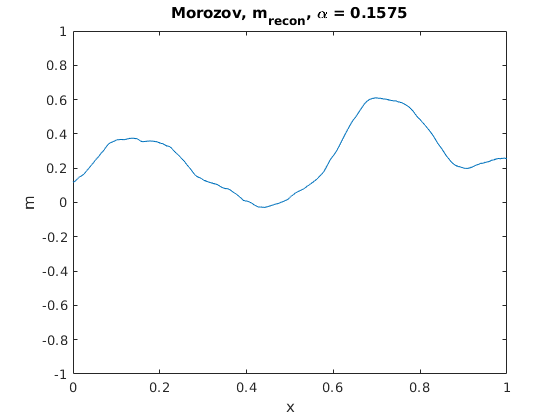

% calculate norm of noise
delta = norm(n);

% find morozov alpha through bisection method
alpha1 = 1e-6;
alpha2 = 1e4;
iterations = 100;
% calculate initial alpha at both points and get misfits
m_alpha1 = (k(x,x)'*k(x,x) + alpha1 * eye(numel(diag(S))))\(k(x,x)'*dn);
m_alpha2 = (k(x,x)'*k(x,x) + alpha2 * eye(numel(diag(S))))\(k(x,x)'*dn);
D_alpha1 = norm(k(x,x)*m_alpha1 - dn);
D_alpha2 = norm(k(x,x)*m_alpha2 - dn);
for i=1:iterations
    % find midpoint
    alpha_mid = (alpha1 + alpha2)/2;
    
    % get misfit at midpoint
    m_alpha_mid = (k(x,x)'*k(x,x) + alpha_mid * eye(numel(diag(S))))\(k(x,x)'*dn);
    D_alpha_mid = norm(k(x,x)*m_alpha_mid - dn);
    
    % check current intervals and assign new intervals
    if D_alpha1 <= delta && delta <= D_alpha_mid
        alpha2 = alpha_mid;
        D_alpha2 = D_alpha_mid;
    elseif D_alpha_mid <= delta && delta <= D_alpha2
        alpha1 = alpha_mid;
        D_alpha1 = D_alpha_mid;
    else
        error(['Optimal alpha outside bounds! \' ...
            'Increase initial alpha search range.'])
    end
end
% get optimal morozov alpha and m
alpha_morozov = (alpha1 + alpha2)/2;
m_alpha_morozov = (k(x,x)'*k(x,x) +...
    alpha_morozov * eye(numel(diag(S))))\(k(x,x)'*dn);

% plot morozov reconstruction
figure; plot(x,m_alpha_morozov); xlim([0,1]); ylim([-1,1]);
title(['Morozov, m_{recon}, \alpha = ', num2str(alpha_morozov)]);
xlabel('x'); ylabel('m');

## Part (e)

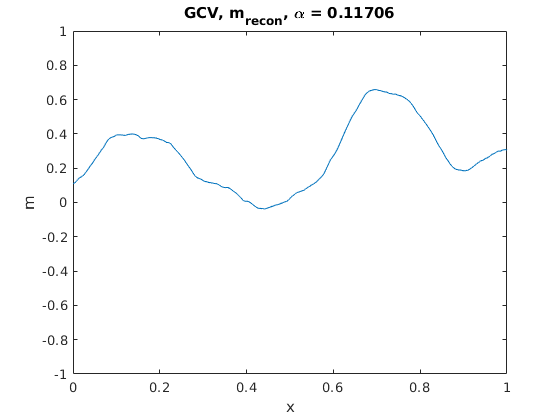

% calculate generalized cross validation estimate
alpha = logspace(-6,4,1000);
m_alpha = zeros(e_m,1000);
GCV = zeros(1000,1);
for i=1:numel(alpha)
    % Get tikhinov recon for given alpha
    mask = diag(S.^2)./(diag(S.^2) + alpha(i));
    k_inv = V*diag(diag(1./S).*mask)*U';
    m_alpha(:,i) = k_inv*dn;
    
    % Calculate GCV estimate
    GCV(i) = numel(x)*(norm(k(x,x)*m_alpha(:,i) - dn)^2)/...
        (trace(eye(r_k,c_k) - k(x,x)*k_inv)^2);
end
% get the optimal GCV alpha
alpha_GCV = min(GCV);
m_alpha_GCV = (k(x,x)'*k(x,x) + alpha_GCV * eye(numel(diag(S))))\(k(x,x)'*dn);

% plot GCV reconstruction
figure; plot(x,m_alpha_GCV); xlim([0,1]); ylim([-1,1]);
title(['GCV, m_{recon}, \alpha = ', num2str(alpha_GCV)]);
xlabel('x'); ylabel('m');

## Part (f)

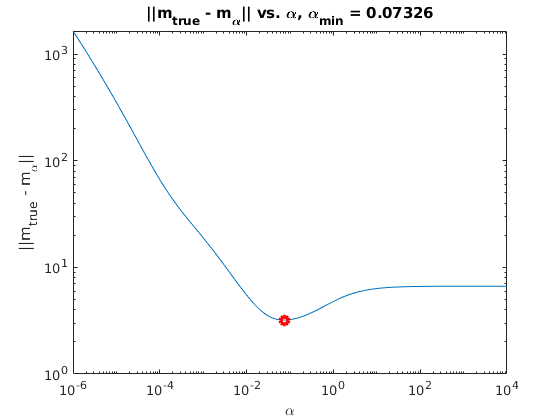

% calculate ||m_true - m_alpha|| for various alphas
L2 = zeros(numel(alpha),1);
for i=1:numel(alpha)
    L2(i) = norm(m_true(x) - m_alpha(:,i));
end
% get min alpha
[min_L2, idx] = min(L2);
min_alpha = alpha(idx);

% plot as the norms as a function of alpha
figure; loglog(alpha,L2); hold on;
loglog(min_alpha, min_L2, 'ro', 'Linewidth', 3);
title(['||m_{true} - m_{\alpha}|| vs. \alpha, \alpha_{min} = ',...
    num2str(min_alpha)]);
xlabel('\alpha'); ylabel('||m_{true} - m_{\alpha}||');